% E 7.2
clear all;

% (a)
syms s K i
Ls = K/(s*(s + 1)*(s^2 + 10*s + 24))

$$Ls = \frac{K}{s\,\left(s+1\right)\,\left(s^{2}+10\,s+24\right)}$$

[n, d] = numden(Ls/K);
num = sym2poly(n);
den = sym2poly(d);
sys = tf([num], [den])

sys =
 
               1
  ----------------------------
  s^4 + 11 s^3 + 34 s^2 + 24 s
 
연속시간 전달 함수입니다.
모델 속성


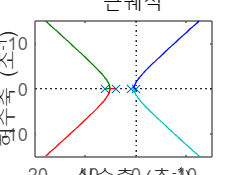

figure();
rlocus(sys);


eqn = 1 + Ls == 0;
s = double(subs(solve(eqn,s),K,8));


size(s,1);

% 복소근만 남기는 함수 start
for i = size(s,1):-1:1
    if abs(s(i)) == abs(real(s(i)))
        s(i) = [];
    end
end
s

s =   -0.4103 - 0.3841i
  -0.4103 + 0.3841i


% 복소근만 남기는 함수 end
% 지배근은 원점에 가장 가까운 켤레 복소근을 말하는 것이므로 답은 이와 같다.

% (b)
omega = sqrt(s(1)*s(2));
zeta = -(s(1)+s(2))/(2*omega);
Ts = 4/(omega*zeta)                                 % 단위 [s]

Ts = 9.7499

PowerOvershoot = 100*exp(-zeta*pi/sqrt(1-zeta^2))   % 단위 [%]

PowerOvershoot = 3.4875

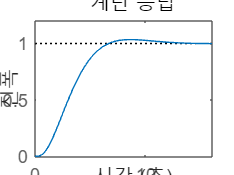


% b를 아래와 같은 방법으로 구할 수도 있다.
syms s
K = 8;
Ls = K/(s*(s + 1)*(s^2 + 10*s + 24));
[n, d] = numden(Ls/(1+Ls));
num = sym2poly(n);
den = sym2poly(d);
sys = tf([num], [den]);
step(sys);

S = stepinfo(sys)

S = 다음 필드를 포함한 struct :
         RiseTime: 4.0083
    TransientTime: 10.8632
     SettlingTime: 10.8632
      SettlingMin: 0.9113
      SettlingMax: 1.0344
        Overshoot: 3.4365
       Undershoot: 0
             Peak: 1.0344
         PeakTime: 8.6432


PO = S.Overshoot     % 단위[%]

PO = 3.4365

Ts = S.SettlingTime  % 단위[초]

Ts = 10.8632